# Compute TF  & TF Covariance Matrix    

# Thierry Lasserre - Last updated: 20/03/2018

## Define 3 KATRIN settings

tbd_5e15   = ref_tfcm('WGTS_CD_MolPerCm2',5e15);

--------------------------------------------------------------------------
ComputeISProbMatrix: 100.00% processed ...
--------------------------------------------------------------------------
ComputeISProbMatrix: #scatt: 00 	Pis=98.84%
ComputeISProbMatrix: #scatt: 01 	Pis=1.059%
ComputeISProbMatrix: #scatt: 02 	Pis=0.007715%
ComputeISProbMatrix: #scatt: 03 	Pis=4.291e-05%
ComputeISProbMatrix: #scatt: 04 	Pis=1.942e-07%
ComputeISProbMatrix: #scatt: 05 	Pis=7.445e-10%
ComputeISProbMatrix: #scatt: 06 	Pis=2.483e-12%
ComputeISProbMatrix: #scatt: 07 	Pis=7.348e-15%
ComputeISProbMatrix: #scatt: 08 	Pis=1.957e-17%
ComputeISProbMatrix: #scatt: 09 	Pis=4.744e-20%
ComputeISProbMatrix: #scatt: 10 	Pis=1.056e-22%
--------------------------------------------------------------------------
ComputeISProbMatrix: trial: 1, #sum scatt = 99.91% 
--------------------------------------------------------------------------


tbd_2p5e17 = ref_tfcm('WGTS_CD_MolPerCm2',2.5e17);

--------------------------------------------------------------------------
ComputeISProbMatrix: 100.00% processed ...
--------------------------------------------------------------------------
ComputeISProbMatrix: #scatt: 00 	Pis=61.35%
ComputeISProbMatrix: #scatt: 01 	Pis=26.94%
ComputeISProbMatrix: #scatt: 02 	Pis=8.768%
ComputeISProbMatrix: #scatt: 03 	Pis=2.262%
ComputeISProbMatrix: #scatt: 04 	Pis=0.4842%
ComputeISProbMatrix: #scatt: 05 	Pis=0.08879%
ComputeISProbMatrix: #scatt: 06 	Pis=0.01428%
ComputeISProbMatrix: #scatt: 07 	Pis=0.002048%
ComputeISProbMatrix: #scatt: 08 	Pis=0.0002656%
ComputeISProbMatrix: #scatt: 09 	Pis=3.146e-05%
ComputeISProbMatrix: #scatt: 10 	Pis=3.433e-06%
--------------------------------------------------------------------------
ComputeISProbMatrix: trial: 1, #sum scatt = 99.91% 
--------------------------------------------------------------------------


tbd_5e17   = ref_tfcm('WGTS_CD_MolPerCm2',5e17);

--------------------------------------------------------------------------
ComputeISProbMatrix: 100.00% processed ...
--------------------------------------------------------------------------
ComputeISProbMatrix: #scatt: 00 	Pis=41.33%
ComputeISProbMatrix: #scatt: 01 	Pis=29.24%
ComputeISProbMatrix: #scatt: 02 	Pis=16.71%
ComputeISProbMatrix: #scatt: 03 	Pis=7.894%
ComputeISProbMatrix: #scatt: 04 	Pis=3.167%
ComputeISProbMatrix: #scatt: 05 	Pis=1.104%
ComputeISProbMatrix: #scatt: 06 	Pis=0.3405%
ComputeISProbMatrix: #scatt: 07 	Pis=0.09432%
ComputeISProbMatrix: #scatt: 08 	Pis=0.02374%
ComputeISProbMatrix: #scatt: 09 	Pis=0.005478%
ComputeISProbMatrix: #scatt: 10 	Pis=0.001168%
--------------------------------------------------------------------------
ComputeISProbMatrix: trial: 1, #sum scatt = 99.91% 
--------------------------------------------------------------------------


## Compute Scattering Probabilities and Transmission Functions for the 3 cases

tbd_5e15_tf    = tbd_5e15.ComputeTF(tbd_5e15.Te,18530);
tbd_2p5e17_tf  = tbd_2p5e17.ComputeTF(tbd_2p5e17.Te,18530);
tbd_5e17_tf    = tbd_5e17.ComputeTF(tbd_5e17.Te,18530);

## Plot Scattering Probabilities for the 3 cases

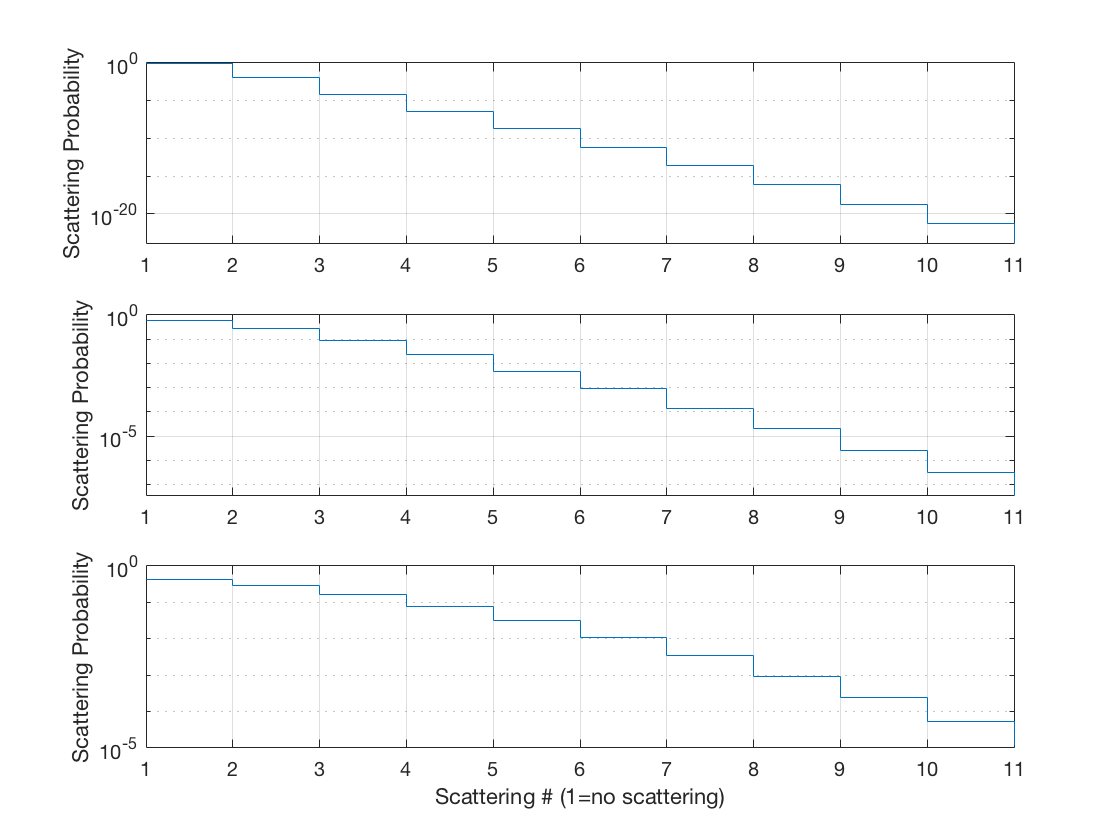

figure(2)
subplot(3,1,1)
p5e15_is = stairs(tbd_5e15.is_Pv);
set(gca, 'YScale', 'log')
subplot(3,1,2)
p2p5e17_is = stairs(tbd_2p5e17.is_Pv);
set(gca, 'YScale', 'log')
subplot(3,1,3)
p5e17_is = stairs(tbd_5e17.is_Pv);
set(gca, 'YScale', 'log')

subplot(3,1,1)
grid on
ylabel('Scattering Probability')
subplot(3,1,2)
grid on
ylabel('Scattering Probability')
subplot(3,1,3)
grid on
xlabel('Scattering # (1=no scattering)')
ylabel('Scattering Probability')

## Plot Transmission Functions for the 3 cases

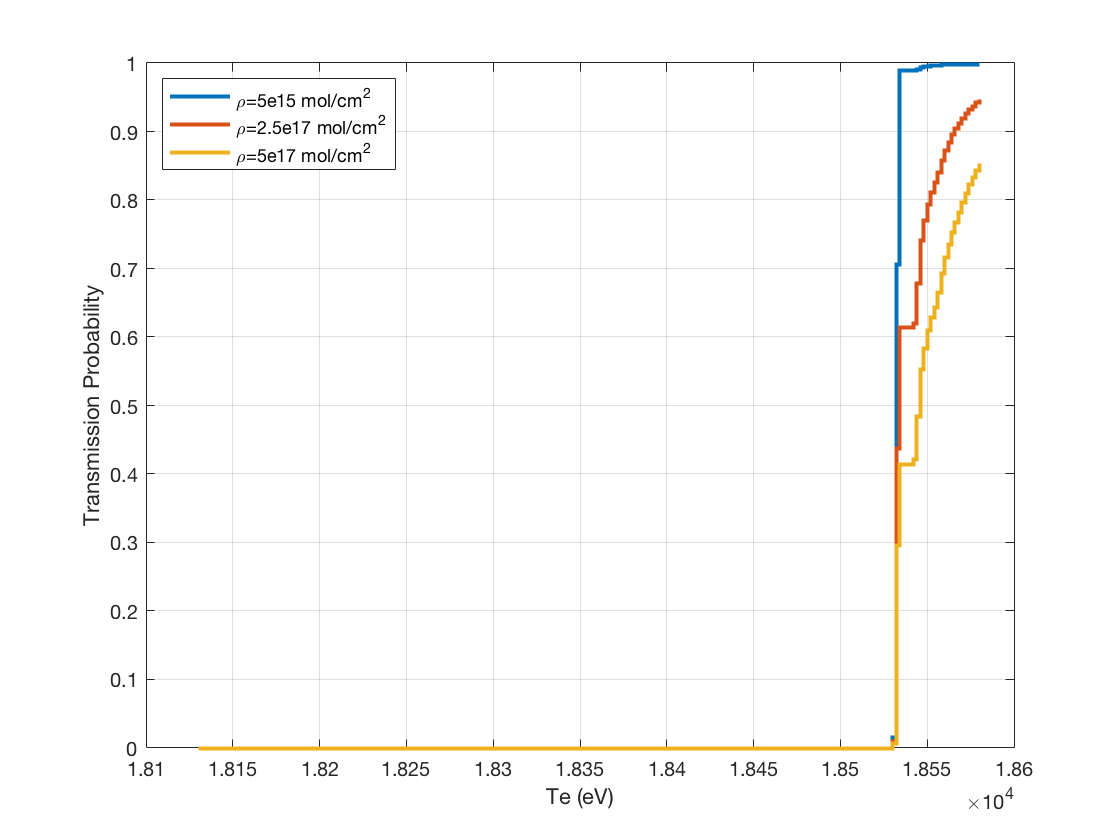

figure(3)
p5e15   = stairs(tbd_5e15.Te,tbd_5e15_tf,'LineWidth',2);
hold on
p2p5e17 = stairs(tbd_2p5e17.Te,tbd_2p5e17_tf,'LineWidth',2);
p5e17   = stairs(tbd_5e17.Te,tbd_5e17_tf,'LineWidth',2);
hold off
xlabel('Te (eV)'); ylabel('Transmission Probability');
legend([p5e15,p2p5e17,p5e17],...
    '\rho=5e15 mol/cm^2','\rho=2.5e17 mol/cm^2','\rho=5e17 mol/cm^2',...
    'Location','NorthWest');
grid on

## Compute and Plot TF's as a function of qU

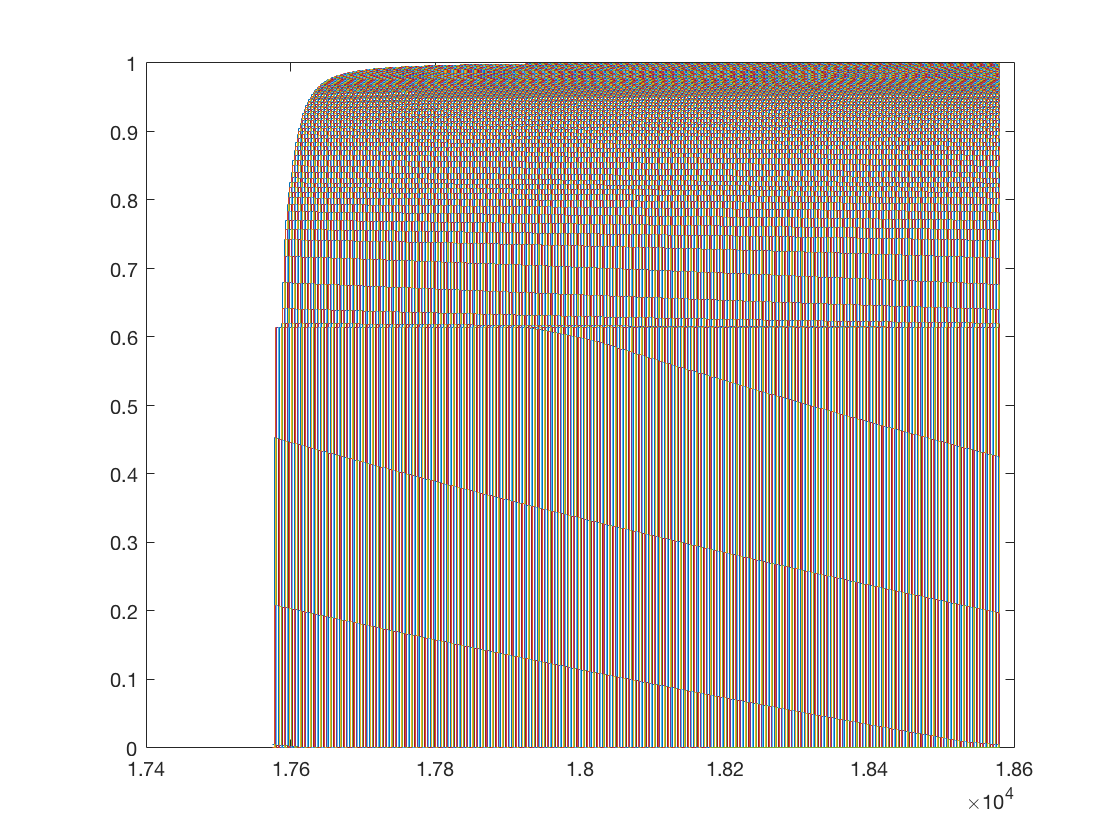

figure(4)
counter=0;
tfqu = zeros(tbd_2p5e17.nTe,tbd_2p5e17.nqU);
for qui=min(tbd_2p5e17.qU):1:max(tbd_2p5e17.qU)
    counter=counter+1;
    tfqu(:,counter) = tbd_2p5e17.ComputeTF(tbd_2p5e17.Te,qui);
    stairs(tbd_2p5e17.Te,tfqu(:,counter))
    hold on
end
hold off

## Superimpose All TF's, at the same 'effective' retarding potential 

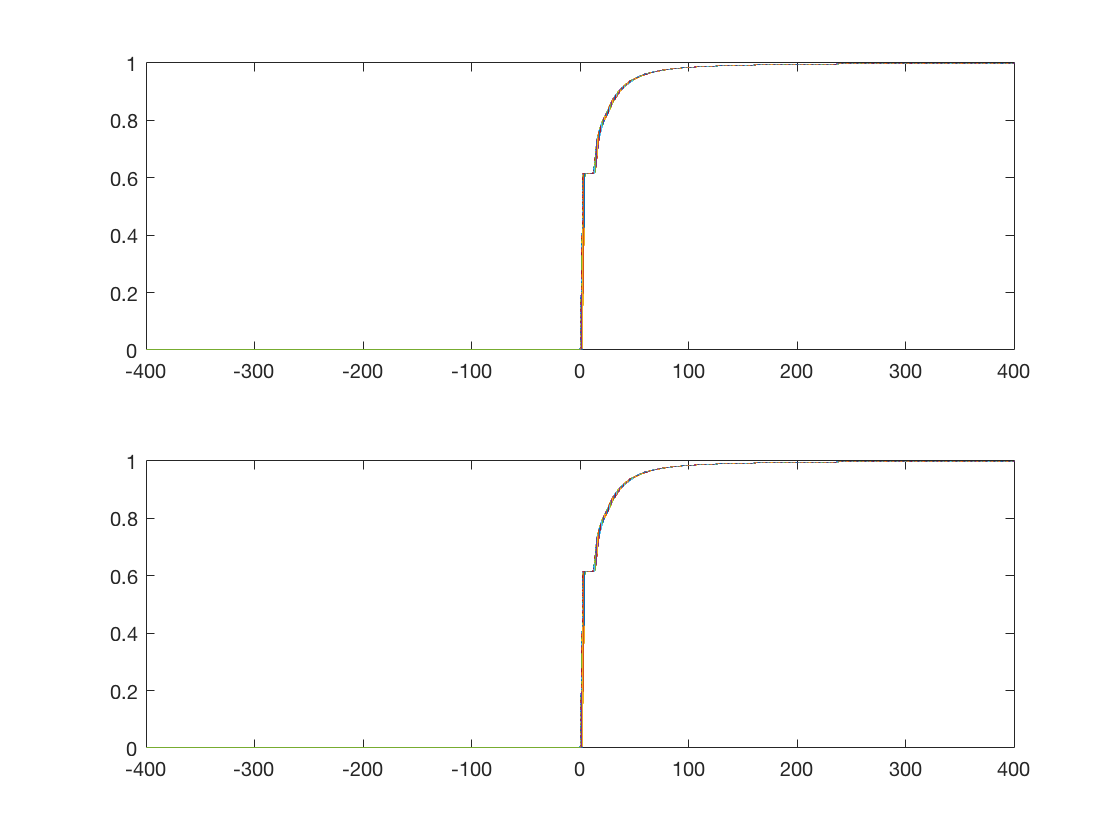

figure(5)
counter=0;
for qui=min(tbd_2p5e17.qU):1:max(tbd_2p5e17.qU)
    counter=counter+1;
    subplot(2,1,1)
    stairs(tbd_2p5e17.Te-qui,tfqu(:,counter))
    hold on
    subplot(2,1,2)
    stairs(tbd_2p5e17.Te-qui,tfqu(:,counter))
    hold on
end
hold off

## Compute Inelastic Scattering Probabilty Matrix

PisCM = tbd_2p5e17.ComputeISProbMatrix(...
    'nTrials',100,'Display','ON',...
    'MACE_Bmax_T_RelErr',1e-2,...
    'WGTS_B_T_RelErr',1e-2,...
    'WGTS_CD_MolPerCm2_RelErr',1e-2);

--------------------------------------------------------------------------
ComputeISProbMatrix: 1.00% processed ...
--------------------------------------------------------------------------
ComputeISProbMatrix: #scatt: 00 	Pis=60.4%
ComputeISProbMatrix: #scatt: 01 	Pis=26.5%
ComputeISProbMatrix: #scatt: 02 	Pis=8.612%
ComputeISProbMatrix: #scatt: 03 	Pis=2.216%
ComputeISProbMatrix: #scatt: 04 	Pis=0.4726%
ComputeISProbMatrix: #scatt: 05 	Pis=0.08627%
ComputeISProbMatrix: #scatt: 06 	Pis=0.0138%
ComputeISProbMatrix: #scatt: 07 	Pis=0.001967%
ComputeISProbMatrix: #scatt: 08 	Pis=0.0002533%
ComputeISProbMatrix: #scatt: 09 	Pis=2.979e-05%
ComputeISProbMatrix: #scatt: 10 	Pis=3.224e-06%
--------------------------------------------------------------------------
ComputeISProbMatrix: trial: 1, #sum scatt = 98.31% 
--------------------------------------------------------------------------
--------------------------------------------------------------------------
ComputeISProbMatrix: 2.00% proc

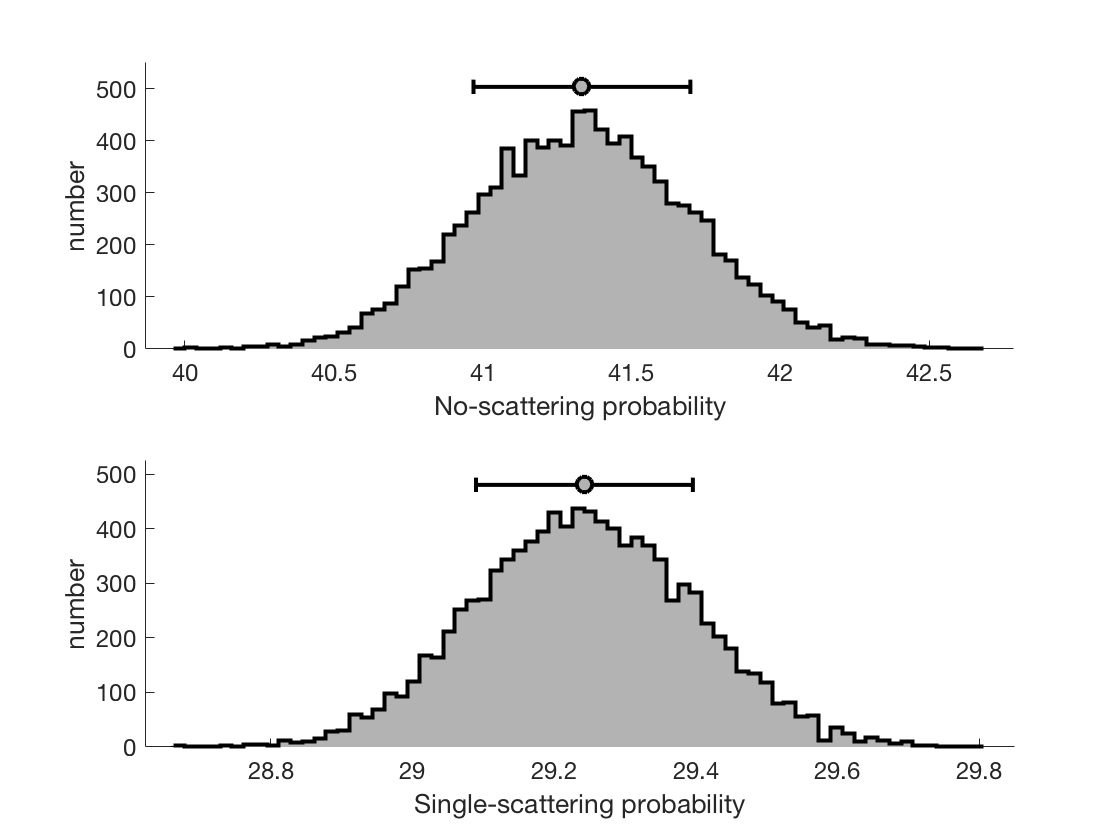

figure(6)
is=load('IS-LookupTable-Trials-10000-5e+17-molPercm2-NIS-11.mat');
subplot(2,1,1)
nhist(is.Pis_m(1,:));
xlabel('No-scattering probability');
subplot(2,1,2)
nhist(is.Pis_m(2,:));
xlabel('Single-scattering probability');

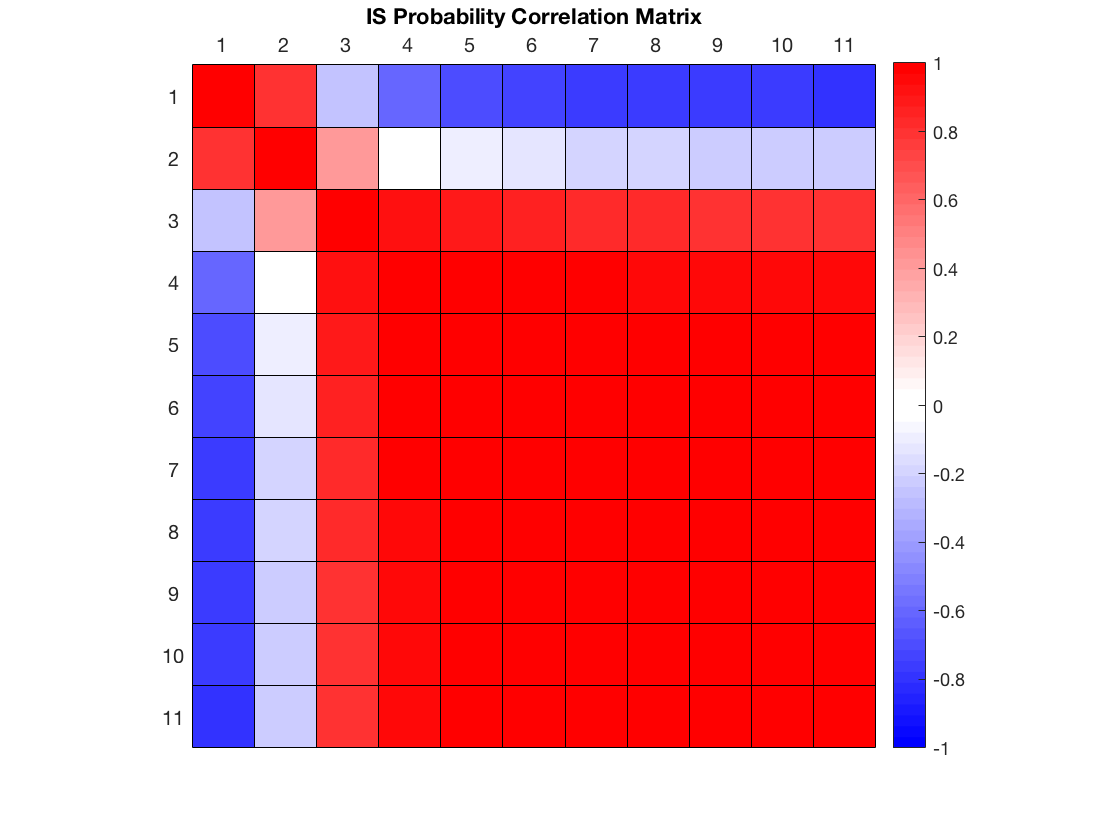


figure(7)
corplot(is.PisCM);
title('IS Probability Correlation Matrix')